
N = 4 % number of data points

N =      4



I = 3 % dimension of data (dimension of each data point) (it is 2 but 

I =      3



% here setting it to 3 to account for weights biases)
% Data points
xp1 = [1 4]; % red (class 0)
xp2 = [3 2]; % blue (class 1)
xp3 = [3 5]; % blue (class 1)
xp4 = [7 3] ;% red (class 0)
% the N x I data matrix
X = [xp2; xp3; xp1; xp4];
X = [ones(1, N); X']' % adding ones to account for weight biases

X =      1     3     2
     1     3     5
     1     1     4
     1     7     3



% Set class 1 = blue, class 0 = red
targets = [0 1 1 0]'; % the N x 1 vector


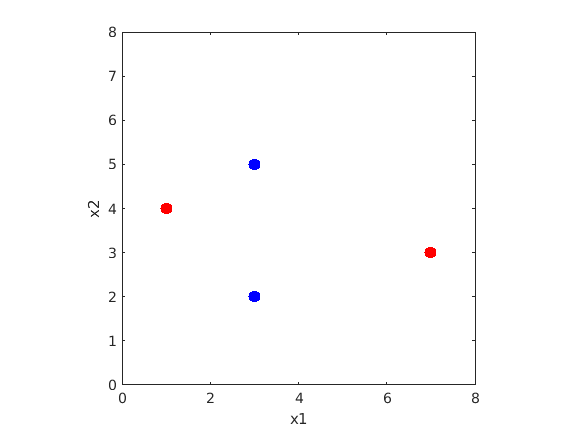


% Plot the data
figure(1); clf
plot(X(1:2, 2), X(1:2, 3), 'b.', 'MarkerSize', 30); % rows 1:5 in data have points belonging to left group
hold on
plot(X(3:4, 2), X(3:4, 3), 'r.', 'MarkerSize', 30) % the rows 6-10 have points belonging to different group
xlim([0 8]); ylim([0 8]); 
xlabel('x1'); ylabel('x2')
axis square
hold on

## Doing error backpropagation

numHiddenUnits = 5

numHiddenUnits =     10


%rng('default')
[Whidden, Wout] = errorBackpropTwoLayer(X, numHiddenUnits, targets);

Whidden

Whidden =    0.235128942851509   0.795513640102449  -0.776714938924144
   0.212264753779301   0.757986074995353  -0.739063732931336
  -0.236576744688543  -0.800137828152631   0.780974352000323


Wout

Wout =   -0.075009600652502  -1.958090474517959  -1.760537014153949   1.982781186359835


rng('default')
[wh, wo] = errorbackpropschool(X, targets);

wh

wh =    0.235128942851509   0.795513640102449  -0.776714938924144
   0.212264753779301   0.757986074995353  -0.739063732931336
  -0.236576744688543  -0.800137828152631   0.780974352000323


wo

wo =   -0.075009600652502  -1.958090474517959  -1.760537014153949   1.982781186359835


## Calculate learned values

learnedY = @(X) sigmoid(Wout * [ones(1, 10000); tanh(Whidden * X')]) ; %yFunc(Whidden, Wout, 10000);
x1 = linspace(0, N);
x2 = x1; 
[x1 x2] = meshgrid(x1, x2);
xs = [ones(10000, 1), x1(:), x2(:)];
learnedY_values = learnedY(xs)

learnedY_values =   Columns 1 through 499

   0.214181985103298   0.241256531271549   0.270743815711894   0.302552456672915   0.336508334461883   0.372350764445165   0.409735112603348   0.448242734521333   0.487398141121603   0.526692154588681   0.565608770664324   0.603652757264647   0.640374883083250   0.675392121468208   0.708401086786203   0.739184088996235   0.767608266111519   0.793619061419060   0.817229749282469   0.838508787733104   0.857566573530471   0.874542813597939   0.889595316140916   0.902890625928331   0.914596625971012   0.924877016424868   0.933887454723562   0.941773081941130   0.948667149517859   0.954690479748365   0.959951528591482   0.964546860358105   0.968561884291144   0.972071739438810   0.975142244985146   0.977830858038471   0.980187600196146   0.982255928746266   0.984073538980825   0.985673091598548   0.987082864291986   0.988327329946518   0.989427665913306   0.990402199930827   0.991266798746232   0.992035205540262   0.992719332041660   0.993329510838

## Plot predictions

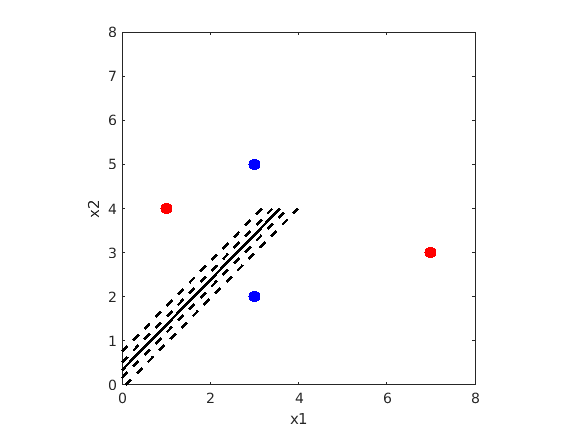

figure(1); clf
plot(X(1:2, 2), X(1:2, 3), 'b.', 'MarkerSize', 30); % rows 1:5 in data have points belonging to left group
hold on
plot(X(3:4, 2), X(3:4, 3), 'r.', 'MarkerSize', 30) % the rows 6-10 have points belonging to different group
xlim([0 8]); ylim([0 8]); 
xlabel('x1'); ylabel('x2')
axis square
hold on

probs = reshape(learnedY_values, 100, 100);
contour(x1 ,x2, probs, 5, '--k', 'LineWidth', 2); hold on
contour(x1 ,x2, probs, 1, 'k', 'LineWidth', 2);